# A Periodic Half Sine wave used to represent a road profile

This function generates a periodic Half-Sine wave signal as shown by the diagam below:

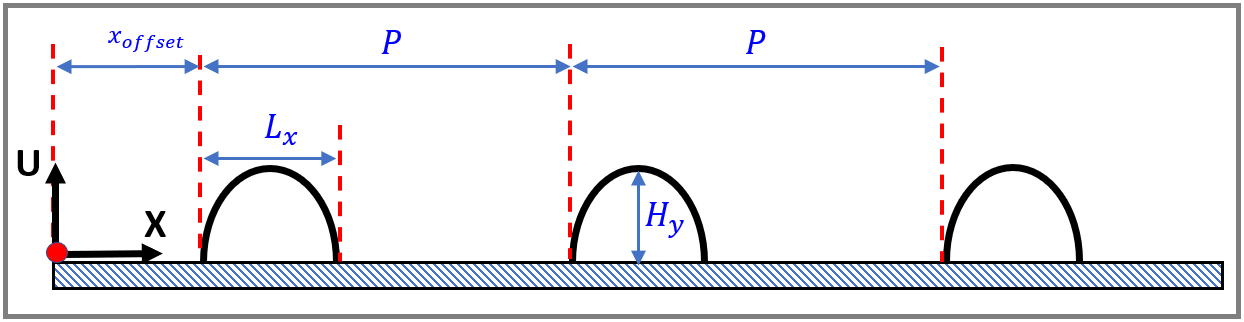

The "Hump" portion is just a simple Sine wave of the form:

- 
$$U\left(x\right)\;={\;H}_Y \ldotp \sin \left(\frac{2\ldotp \pi \ldotp x}{\lambda }\right)\;=\;{\;H}_Y \ldotp \sin \left(\frac{2\ldotp \pi \ldotp x}{2\ldotp L_X }\right)\;=\;\;\;H_Y \ldotp \sin \left(\frac{\pi \ldotp x}{L_X }\right)$$


### Function INPUTS:

- `   x        :`    a list of **X-values** at which to compute the height of the road

- `   x_offset :`    the horizontal distance at which the FIRST hump begins

- `   Lx       :`    the **width** of the hump

- `   Hy       :`    the **Height** of the Hump

- `   P        :`    the spatial Period of the repeating block

### Function OUTPUTS:

- `   U        :`    the HEIGHT of the road at the specified **X-values**

 **NOTE:  **The [`arguments`](matlab:  web(fullfile(docroot, 'matlab/ref/arguments.html'))) code block is NOT supported by MATLAB Coder. See comments at the bottom of this file.

function U = bh_road_profile_half_sine_periodic(x, x_offset, Lx, Hy, P)
  arguments
     x              double  {mustBeVector}
     x_offset (1,1) double  {mustBeNonnegative}
     Lx       (1,1) double  {mustBePositive}
     Hy       (1,1) double  
     P        (1,1) double  {mustBePositive, mustBeGreaterThan(P, Lx)}     
  end
  
   Xc = x - x_offset;
   
   U  = zeros(size(Xc));
   N  = length(Xc);
   
   for kk=1:N

       x_pnt = Xc(kk);

      if(x_pnt<0)
           U(kk) = 0;
      else % x > 0
           x_mod = mod(x_pnt,P); 
           
          if(x_mod <= Lx & x_mod>=0)
              
              U(kk) = Hy * sin(pi*x_mod/Lx);
              
          elseif(x_mod > Lx & x_mod <= P) 
              U(kk) = 0;
          end
      end
   end % for
   
end % function

# **An Appendix:**

 **NOTE:  **The [`arguments`](matlab:  web(fullfile(docroot, 'matlab/ref/arguments.html'))) code block is NOT supported by MATLAB Coder. 

- So, *IFFF* you wanted to use MATLAB Coder you would need to replace the arguments block with a series of [`assert`](matlab:  web(fullfile(docroot, 'matlab/ref/assert.html'))) statements to accomplish the same behaviour, eg: